%% Calibração do sensor VL53L0X
% Ajuste linear por mínimos quadrados
% Objetivo: obter uma reta para converter a leitura filtrada do sensor
% em distância real.

clear; clc; close all;

%% Dados experimentais
% Distância real (mm)
Y = [30 35 40 45 50 55 60 65 70 75 80 85]';

% Leituras médias de cada repetição (mm)
L1 = [50.27 56.56 61.24 67.65 72.43 77.74 82.49 88.16 94.49 98.06 103.72 107.96]';
L2 = [49.65 55.86 62.01 67.81 73.67 77.27 83.62 88.71 92.99 98.30 103.43 108.51]';
L3 = [51.05 56.57 61.90 67.82 73.53 77.28 83.06 88.07 94.55 99.72 104.01 109.43]';

% Excluir X primeiras linhas e Y segundas linhas
% Leitura média final (mm)
X = mean([L1 L2 L3], 2);

%% Ajuste linear: Y = Ganho*X + Polarizacao
Xm = [X ones(length(X),1)];
ab = Xm \ Y;

Ganho = ab(1)

Ganho = 0.9470

Polarizacao = ab(2)

Polarizacao = -18.5098


% Reta estimada nos pontos medidos
Yest = Ganho*X + Polarizacao;

%% Métricas do ajuste
erro = Y - Yest;
R2 = 1 - sum((Y - Yest).^2) / sum((Y - mean(Y)).^2)

R2 = 0.9992

MAE = mean(abs(erro))

MAE = 0.3753

RMSE = sqrt(mean(erro.^2))

RMSE = 0.4736

ErroMaxAbs = max(abs(erro))

ErroMaxAbs = 0.8552

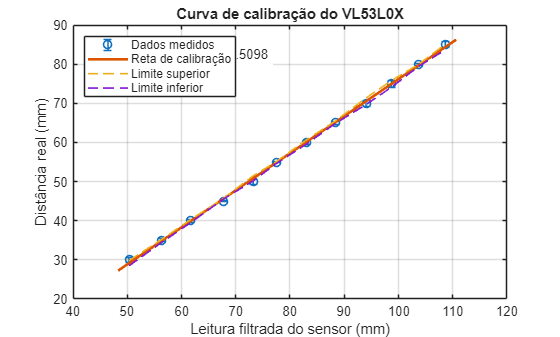


%% Incerteza / repetibilidade a partir das 3 repetições
% Desvio-padrão das leituras em cada ponto (no eixo X)
incerteza_X = std([L1 L2 L3], 0, 2);

% Propagação aproximada para Y usando a sensibilidade da reta
incerteza_Y = abs(Ganho) * incerteza_X;

Ysup = Yest + incerteza_Y;
Yinf = Yest - incerteza_Y;

%% Para desenhar a reta suavemente
Xlinha = linspace(min(X)-2, max(X)+2, 300);
Ylinha = Ganho*Xlinha + Polarizacao;

%% GRÁFICO 1 - Curva de calibração
figure;
hold on;
grid on;
box on;

% Dados medidos com barra de erro vertical propagada
h1 = errorbar(X, Y, incerteza_Y, 'o', 'LineWidth', 1.2, 'MarkerSize', 6);

% Reta de calibração
h2 = plot(Xlinha, Ylinha, '-', 'LineWidth', 2);

% Limites superior e inferior nos pontos medidos
h3 = plot(X, Ysup, '--', 'LineWidth', 1.2);
h4 = plot(X, Yinf, '--', 'LineWidth', 1.2);

legend([h1 h2 h3 h4], ...
       'Dados medidos', ...
       'Reta de calibração', ...
       'Limite superior', ...
       'Limite inferior', ...
       'Location', 'northwest');

xlabel('Leitura filtrada do sensor (mm)');
ylabel('Distância real (mm)');
title('Curva de calibração do VL53L0X');

texto = sprintf('Y = %.4fX %+ .4f\nR^2 = %.5f', Ganho, Polarizacao, R2);
text(min(X)+2, max(Y)-5, texto, 'FontSize', 10, 'BackgroundColor', 'white');

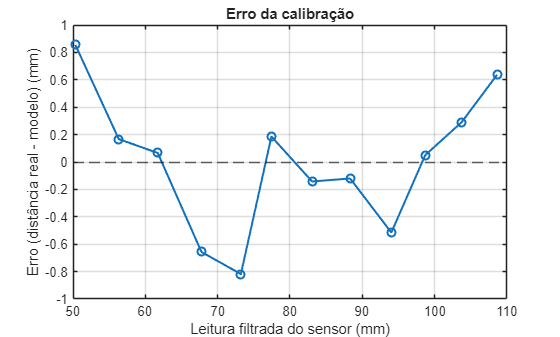


%% GRÁFICO 2 - Erro da calibração
figure;
plot(X, erro, 'o-', 'LineWidth', 1.5, 'MarkerSize', 6);
hold on;
yline(0, '--');
grid on;
box on;

xlabel('Leitura filtrada do sensor (mm)');
ylabel('Erro (distância real - modelo) (mm)');
title('Erro da calibração');


%% Tabela-resumo no Command Window
Tabela = table(Y, L1, L2, L3, X, Yest, erro, incerteza_X, incerteza_Y, ...
    'VariableNames', {'DistReal_mm','Leitura1_mm','Leitura2_mm','Leitura3_mm', ...
    'MediaFinal_mm','Modelo_mm','Erro_mm','IncertezaX_mm','IncertezaY_mm'});

disp(Tabela);

    DistReal_mm    Leitura1_mm    Leitura2_mm    Leitura3_mm    MediaFinal_mm    Modelo_mm    Erro_mm     IncertezaX_mm    IncertezaY_mm
    ___________    ___________    ___________    ___________    _____________    _________    ________    _____________    _____________

        30            50.27          49.65          51.05          50.323         29.145       0.85517       0.70152          0.66432   
        35            56.56          55.86          56.57           56.33         34.833       0.16703       0.40706          0.38548   
        40            61.24          62.01           61.9          61.717         39.934      0.066024       0.41645          0.39437   
        


%% Equação final para uso prático
fprintf('\nEquação de calibração para uso no Arduino/MATLAB:\n');


Equação de calibração para uso no Arduino/MATLAB:


fprintf('dist_real_mm = %.6f * leitura_filtrada_mm %+ .6f\n', Ganho, Polarizacao);

dist_real_mm = 0.946970 * leitura_filtrada_mm -18.509836
